# Reanalysis of Stefanini *et al.* 2020

The neural data is taken at 5Hz.

top_dir = '../fabio_data';

behavior = {'dhpc08_behavior.txt', 'dhpc09_behavior.txt', 'dhpc10_behavior.txt'};
neural_data = {'dhpc08_cnmfe_spikes.txt', 'dhpc09_cnmfe.mat', 'dhpc10_cnmfe.mat'};

f_ = @(x) fullfile(top_dir, x);
S9 = OpenField(f_(behavior{2}), f_(neural_data{2}));

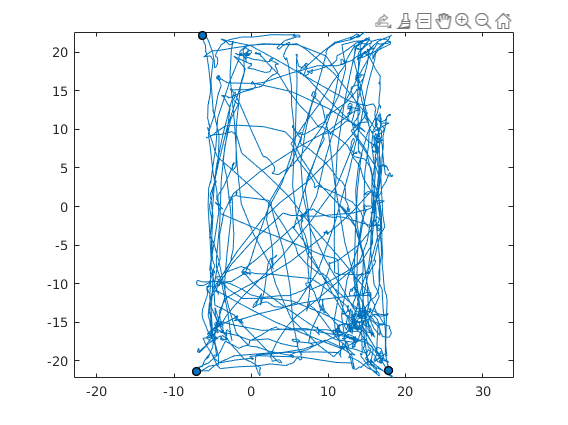

S9 = S9.select_boundary_points;

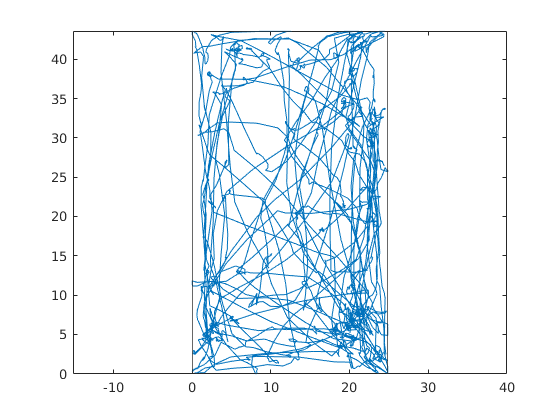

S9.plot_ortho_pos;

%{
alg = my_algs('ecoclin'); % Do 10 fold cross-validation in continuous time (not random frames)
K = 10;

%X = S9.traces.';
[X, ks] = S9.get_dataset;
fold = floor((0:numel(ks)-1) ./ numel(ks) * K) + 1;
dec_error = zeros(1,K);
progressbar('folds...');
for i = 1:K
    train_filt = fold ~= i;
    test_filt = fold == i;
    
    X_train = X(train_filt, :);
    ks_train = ks(train_filt);
    X_test = X(test_filt, :);
    ks_test = ks(test_filt);
    
    mdl = alg.train(X_train, ks_train);
    ps_test = alg.test(mdl, X_test);
    
    dpos_test = S9.ks2dpos(ks_test);
    pred_dpos_test = S9.ks2dpos(ps_test);
    dec_error(i) = mean(sqrt(sum((dpos_test - pred_dpos_test).^2,2)));
    progressbar(i/K);
end
mean_dec_error = mean(dec_error);
std_dec_error = std(dec_error);
fprintf('Decoding error was %f (cm) +- %f\n', mean_dec_error * 5, std_dec_error * 5);
%}

Non continuous data decoding (like our shuffling method):

[dec_error, me, me_s] = S9.decode(false, false);
fprintf('Decoding error was %f (cm) +- %f\n', me * 5, me_s * 5);

Decoding error was 20.625098 (cm) +- 11.754889


[dec_error_shuf, me_shuf, me_s_shuf] = S9.decode(true, false);
fprintf('Shuffled decoding error was %f (cm) +- %f\n', me_shuf * 5, me_s_shuf * 5);

Shuffled decoding error was 11.393027 (cm) +- 12.532582


Continuous data decoding (like Stefanini's shuffling method):

# TODO!!!: change error metric to use (x,y) position for continuous data decoder

[dec_error, me, me_s] = S9.decode(false, true);

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 15).


fprintf('Decoding error was %f (cm) +- %f\n', me * 5, me_s * 5);

Decoding error was 13.285649 (cm) +- 10.930216


[dec_error_shuf, me_shuf, me_s_shuf] = S9.decode(true, true);
fprintf('Shuffled decoding error was %f (cm) +- %f\n', me_shuf * 5, me_s_shuf * 5);

Shuffled decoding error was 8.931130 (cm) +- 10.973469


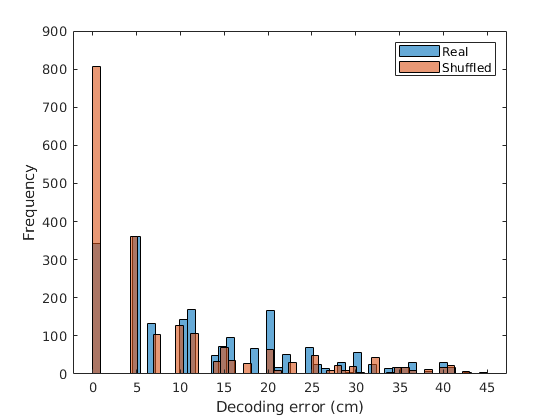

figure;
histogram(dec_error * 5, 50);
hold on;
histogram(dec_error_shuf * 5, 50);
xlabel 'Decoding error (cm)'
ylabel 'Frequency'
legend Real Shuffled

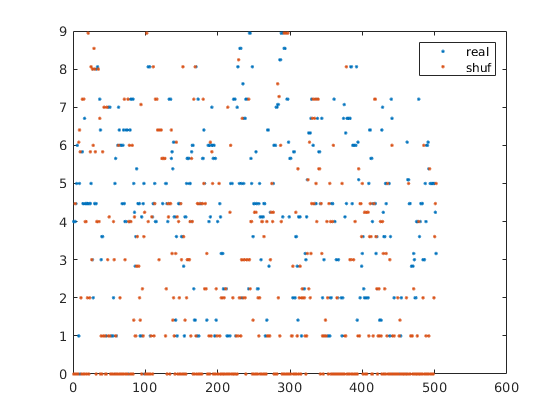

figure;
plot(dec_error, '.'); hold on;
plot(dec_error_shuf, '.');
legend real shuf

## Using a continuous decoder

[X_cont, y_cont, ks] = S9.get_continuous_dataset;
X_cont_shuf = fshuffle(X_cont, ks, false);
X_cont_shuf_auto = fshuffle(X_cont, ks, true);

[real_e, real_nn_rms, real_nn_val_rms, real_nn_train_rms] = two_layer_net(X_cont, y_cont);
[shuf_e, shuf_nn_rms, shuf_nn_val_rms, shuf_nn_train_rms] = two_layer_net(X_cont_shuf, y_cont);
[autoshuf_e, autoshuf_nn_rms, autoshuf_nn_val_rms, autoshuf_nn_train_rms] = two_layer_net(X_cont_shuf_auto, y_cont);

tab(1,1) = real_nn_rms;
tab(2,1) = real_nn_val_rms;
tab(3,1) = real_nn_train_rms;

tab(1,2) = shuf_nn_rms;
tab(2,2) = shuf_nn_val_rms;
tab(3,2) = shuf_nn_train_rms;

tab(1,3) = autoshuf_nn_rms;
tab(2,3) = autoshuf_nn_val_rms;
tab(3,3) = autoshuf_nn_train_rms;

tab = array2table(tab, "RowNames",{'Test', 'Validation', 'Train'}, "VariableNames",{'Real', 'Shuf', 'Autoshuf'})

tab = 3×3 table
                   Real      Shuf     Autoshuf
                  ______    ______    ________

    Test          11.185    9.7879     11.321 
    Validation       NaN       NaN        NaN 
    Train         9.6085    9.2521     9.6704 


real_dist_e = vecnorm(real_e);
shuf_dist_e = vecnorm(shuf_e);

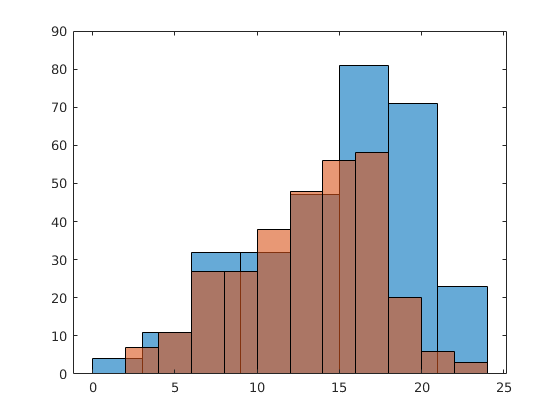

figure;
histogram(real_dist_e(end-300:end));
hold on;
histogram(shuf_dist_e(end-300:end));

real_test_median = median(real_dist_e(end-300:end))

real_test_median = 16.0114

shuf_test_median = median(shuf_dist_e(end-300:end))

shuf_test_median = 13.7401